clc
clear
addpath 'C:\Users\Admin\AppData\Roaming\MathWorks\MATLAB Add-Ons\Functions\Shapiro-Wilk and Shapiro-Francia normality tests'



% 选择 .xlsx 文件
[fileName, filePath] = uigetfile('*.xlsx', '选择 .xlsx 文件');
if fileName == 0
    error('未选择文件');
end
fullFilePath = fullfile(filePath, fileName);


% 加载数据
data = readmatrix(fullFilePath);
if isempty(data)
    error(['文件 ', fileName, ' 为空或格式不正确']);
end
[timepoints, n] = size(data);

% 初始化变量
selectedFrames = nan(1, n);     % 各细胞选择的起始帧
windowSizes = 200 * ones(1, n); % 各细胞的基线窗口大小（默认为200帧）
F0 = zeros(1, n);              % 预分配 F0

% 将数据转移到 GPU
if canUseGPU()
    data = gpuArray(data);
    disp('使用 GPU 加速计算');
else
    warning('未检测到 GPU，使用 CPU 计算');
end

使用 GPU 加速计算


Cell 1: 左键选择起始点 | 右键设置窗口大小 | 回车确认


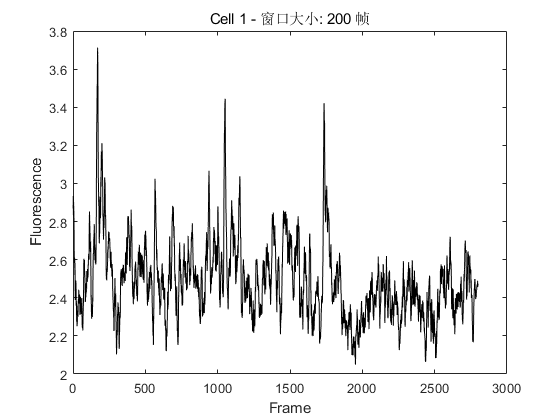

Cell 1: 左键选择起始点 | 右键设置窗口大小 | 回车确认


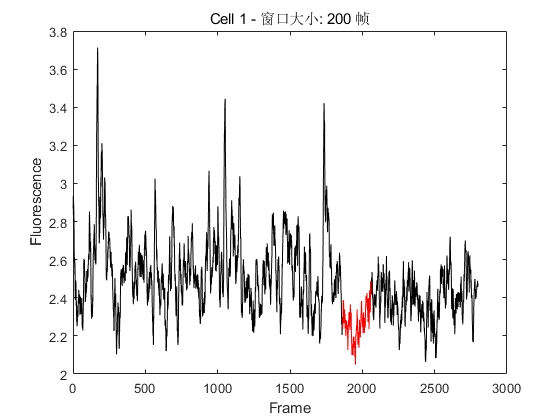

Cell 2: 左键选择起始点 | 右键设置窗口大小 | 回车确认


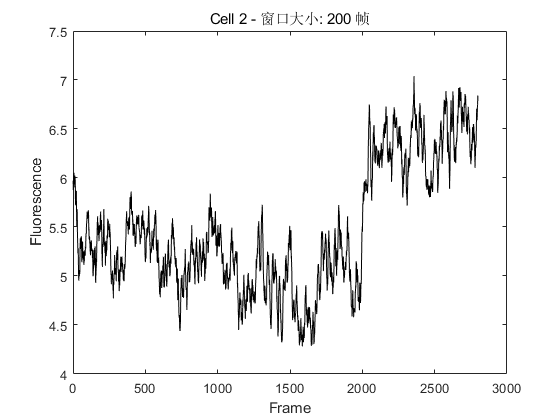

Cell 2: 左键选择起始点 | 右键设置窗口大小 | 回车确认


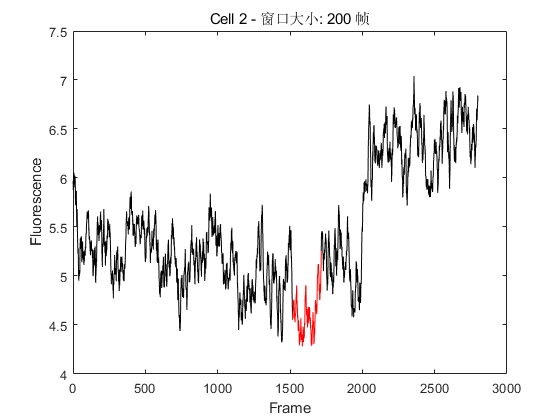

Cell 3: 左键选择起始点 | 右键设置窗口大小 | 回车确认


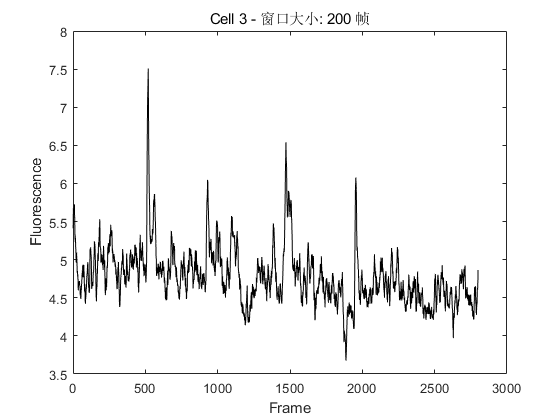

Cell 3: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 4: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 4: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 4: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 5: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 5: 左键选择起始点 | 右键设置窗口大小 | 回车确认


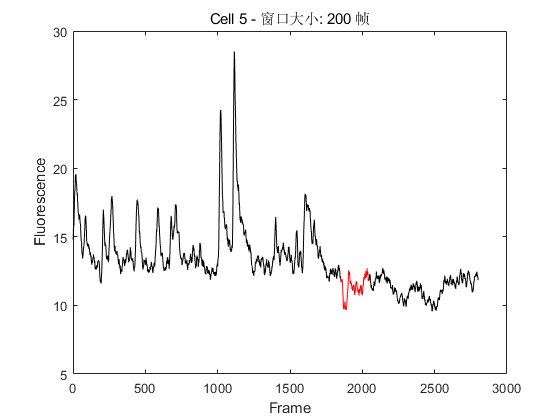

Cell 6: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 6: 左键选择起始点 | 右键设置窗口大小 | 回车确认


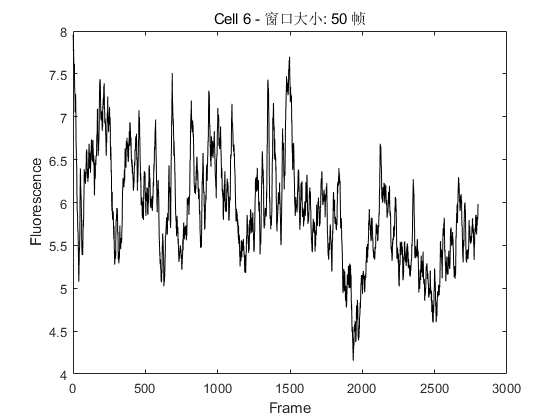

Cell 6: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 6: 左键选择起始点 | 右键设置窗口大小 | 回车确认


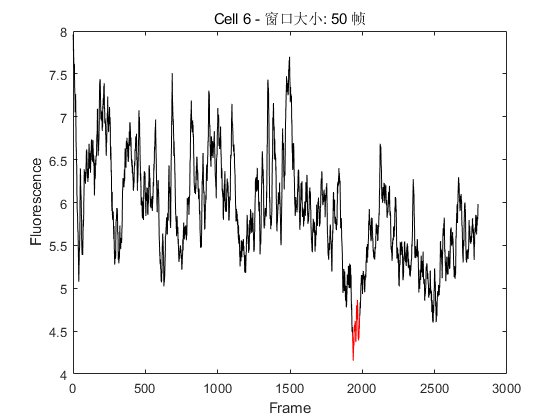

Cell 7: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 7: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 7: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 7: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 8: 左键选择起始点 | 右键设置窗口大小 | 回车确认


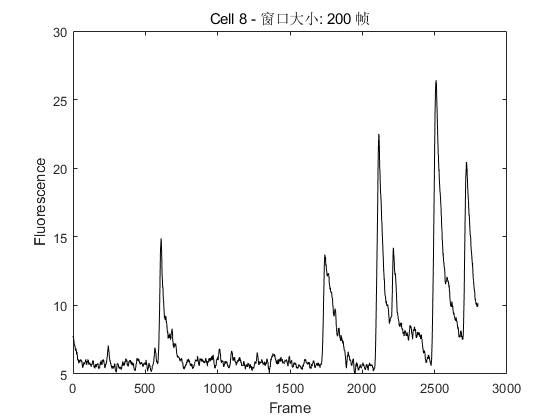

Cell 8: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 9: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 9: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 9: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 10: 左键选择起始点 | 右键设置窗口大小 | 回车确认


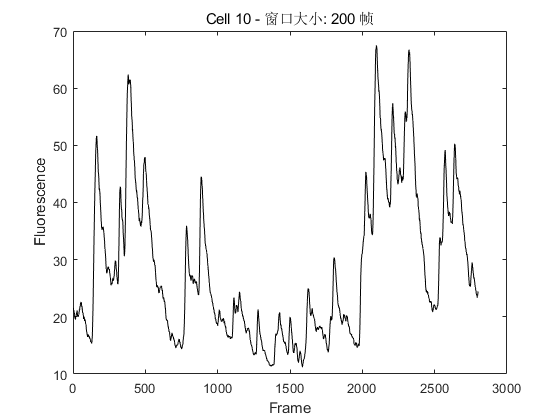

Cell 10: 左键选择起始点 | 右键设置窗口大小 | 回车确认


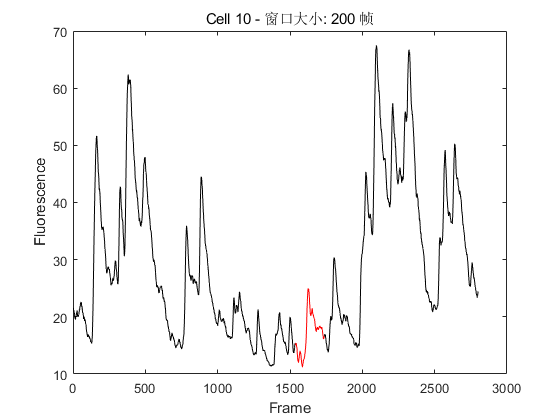

Cell 10: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 10: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 10: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 11: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 11: 左键选择起始点 | 右键设置窗口大小 | 回车确认


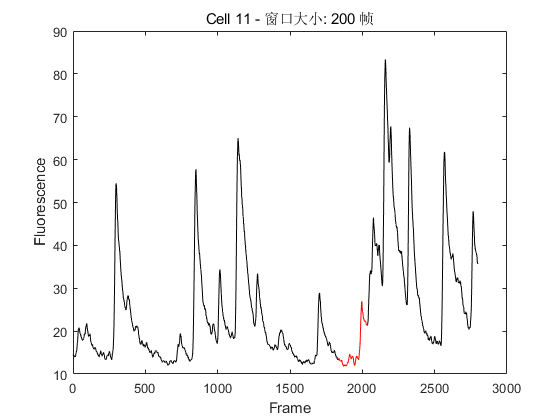

Cell 11: 左键选择起始点 | 右键设置窗口大小 | 回车确认


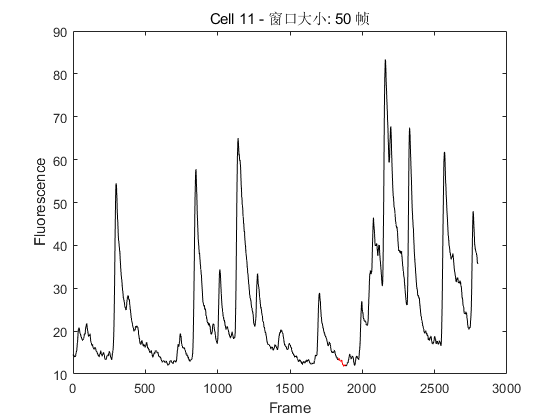

Cell 11: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 11: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 12: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 12: 左键选择起始点 | 右键设置窗口大小 | 回车确认


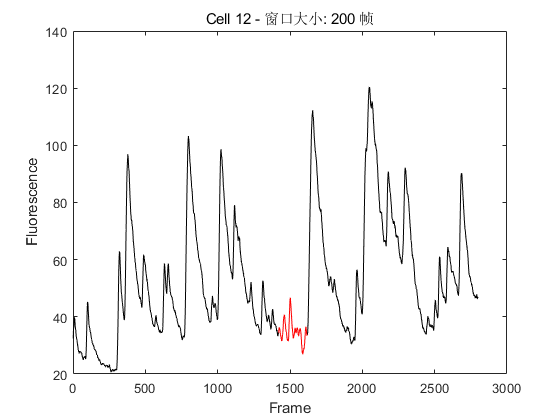

Cell 12: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 12: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 13: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 13: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 14: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 14: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 14: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 14: 左键选择起始点 | 右键设置窗口大小 | 回车确认


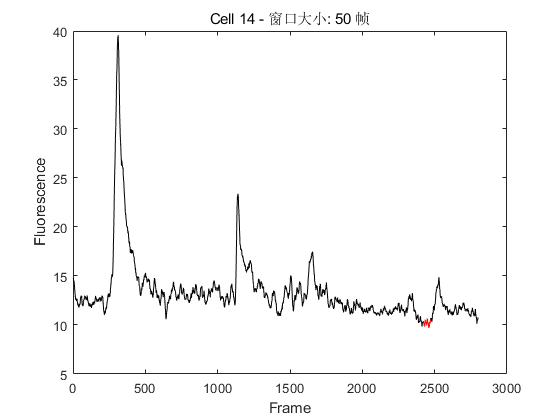

Cell 15: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 15: 左键选择起始点 | 右键设置窗口大小 | 回车确认


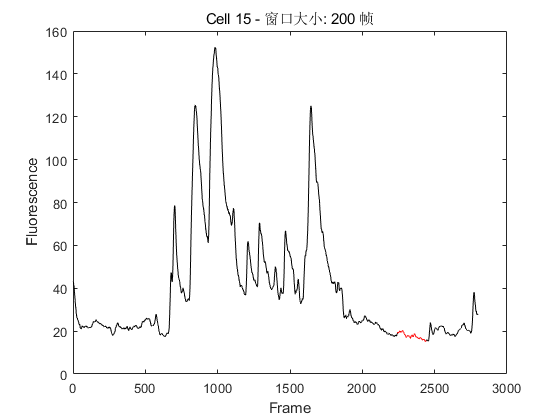

Cell 16: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 16: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 16: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 17: 左键选择起始点 | 右键设置窗口大小 | 回车确认


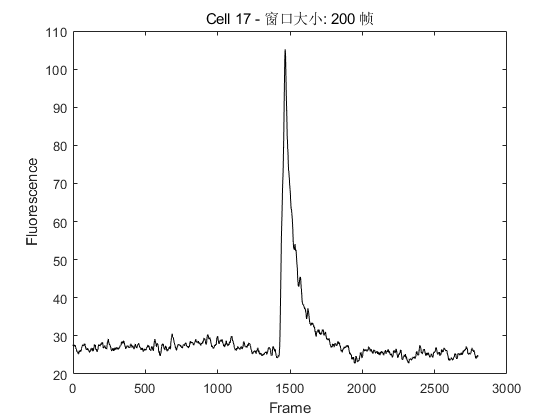

Cell 17: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 18: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 18: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 19: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 19: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 20: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 20: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 21: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 21: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 22: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 22: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 23: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 24: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 24: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 24: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 25: 左键选择起始点 | 右

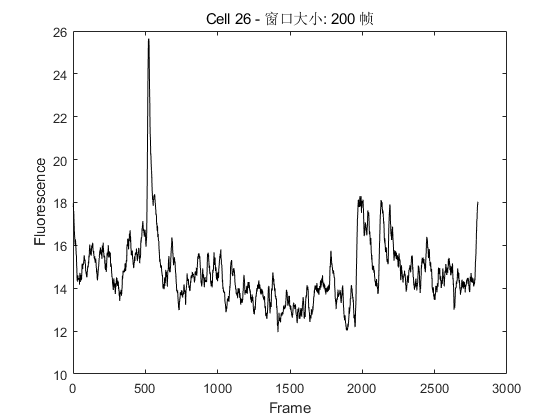

Cell 26: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 27: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 27: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 28: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 28: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 28: 左键选择起始点 | 右键设置窗口大小 | 回车确认


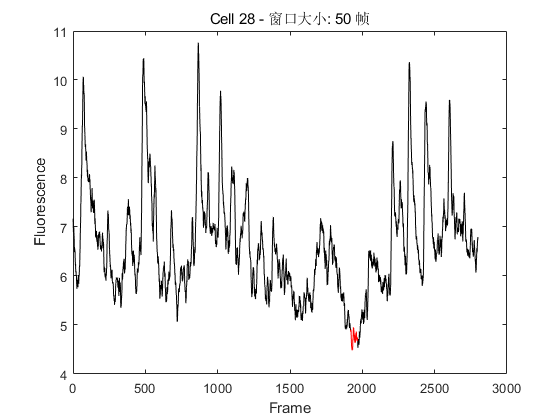

Cell 29: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 29: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 30: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 30: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 31: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 31: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 31: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 32: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 32: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 33: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 33: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 33: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 33: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 33: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 34: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 34: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 35: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 35: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 36: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 36: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 37: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 37: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认


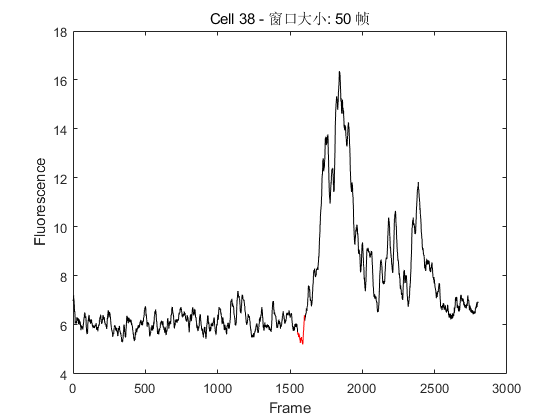

Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 38: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 39: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 39: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 39: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 40: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 40: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 40: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 41: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 41: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 41: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 42: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 42: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 42: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 43: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 44: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 44: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 44: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 45: 左键选择起始点 | 右键设置窗口大小 | 回车确认


Cell 45: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 45: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 45: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 45: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 46: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 46: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 47: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 47: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 47: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 48: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 48: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 48: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 48: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 49: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 49: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 49: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 50: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 50: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 50: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 51: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 51: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 51: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 52: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 52: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 53: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 53: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 53: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 53: 左键选择起始点 | 右键设置窗口大小 | 回车确认
Cell 54: 左键选择起始点 | 右


% -----------------------------
% 主处理循环：选择基线窗口
% -----------------------------
for i = 1:n
    currentData = data(:, i);   % 当前细胞数据
    windowSize = windowSizes(i);% 当前窗口大小
    selectedFrame = nan;        % 重置当前细胞的选择
    
    % 交互式选择基线窗口
    while true
        hFig = figure;
        set(hFig, 'ToolBar', 'none');
        
        try
            % 绘制荧光轨迹
            cla;
            plot(currentData, 'k');
            title(['Cell ', num2str(i), ' - 窗口大小: ', num2str(windowSize), ' 帧']);
            xlabel('Frame');
            ylabel('Fluorescence');
            hold on;
            
            % 绘制已选窗口
            if ~isnan(selectedFrame)
                endFrame = min(selectedFrame + windowSize - 1, timepoints);
                plot(selectedFrame:endFrame, currentData(selectedFrame:endFrame), 'r');
            end
            
            % 用户交互提示
            disp(['Cell ', num2str(i), ': 左键选择起始点 | 右键设置窗口大小 | 回车确认']);
            
            % 捕获用户输入
            [x, ~, button] = ginput(1);
            
            if isempty(button)  % 回车确认选择
                if ~isnan(selectedFrame)
                    selectedFrames(i) = selectedFrame;
                    close(hFig);
                    break;
                else
                    warning('未选择有效窗口，继续选择');
                end
            elseif button == 1  % 左键选择起始点
                startFrame = round(x(1));
                if (startFrame >= 1) && (startFrame + windowSize - 1 <= timepoints)
                    selectedFrame = startFrame;
                else
                    warning('所选窗口超出时间范围');
                end
            elseif button == 3  % 右键修改窗口大小
                answer = inputdlg('输入新的窗口大小（帧数）:', '窗口设置', [1 40], {num2str(windowSize)});
                if ~isempty(answer)
                    newSize = str2double(answer{1});
                    if ~isnan(newSize) && (newSize > 0) && (newSize == floor(newSize))
                        % 更新窗口大小并验证当前选择
                        windowSizes(i) = newSize;
                        windowSize = newSize;
                        if ~isnan(selectedFrame) && (selectedFrame + newSize - 1 > timepoints)
                            warning('新窗口超出时间范围，请重新选择起始点');
                            selectedFrame = nan;
                        end
                    else
                        warning('请输入正整数');
                    end
                end
            end
            close(hFig);
            
        catch ME
            close(hFig);
            if contains(ME.message, '索引超出矩阵维度')
                warning('窗口超出数据范围，请重新选择');
            else
                rethrow(ME);
            end
        end
    end
    
    % 计算F0
    if ~isnan(selectedFrames(i))
        F0(i) = mean(currentData(selectedFrames(i):selectedFrames(i)+windowSizes(i)-1));
    else
        F0(i) = NaN;
        warning(['Cell ', num2str(i), ' 未选择有效基线窗口']);
    end
end


% -----------------------------
% 计算 delta F/F
% -----------------------------
delta_F_over_F = (data - F0) ./ F0;

% 将结果从 GPU 移回 CPU（如果需要）
if isgpuarray(delta_F_over_F)
    delta_F_over_F = gather(delta_F_over_F);
    F0 = gather(F0);
end



% -----------------------------
% Shapiro-Wilk 正态性检验
% -----------------------------
disp('---------- Shapiro-Wilk 正态性检验 ----------');

---------- Shapiro-Wilk 正态性检验 ----------


validF0 = F0(~isnan(F0));
if length(validF0) > 3
    [h, p] = swtest(validF0);
    if h == 0
        disp('F0 值服从正态分布');
    else
        disp('F0 值不服从正态分布');
    end
    disp(['p 值 = ', num2str(p)]);
else
    disp('数据不足，无法进行 Shapiro-Wilk 检验');
end

F0 值不服从正态分布


p 值 = 2.0409e-10


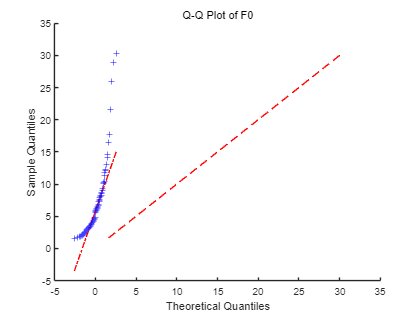


% -----------------------------
% 绘制 Q-Q 图
% -----------------------------
figure;
qqplot(validF0);
title('Q-Q Plot of F0');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
hold on;
plot([min(validF0), max(validF0)], [min(validF0), max(validF0)], '--r');
hold off;


% -----------------------------
% 保存结果
% -----------------------------
[~, name, ~] = fileparts(fileName);
savePath = fullfile(filePath, [name, '_F.xlsx']);
if exist(savePath, 'file'), delete(savePath); end
writematrix(delta_F_over_F, savePath, 'Sheet', 'DeltaFOverF');
disp(['文件已保存至: ', savePath]);

文件已保存至: E:\Data Analysis\2P Imaging\2024 June Data processing\Mice4_vgatAi9_ACC_0430\Intensity\intensity_t6_CS_mean_F.xlsx



% -----------------------------
% GPU 可用性检查函数
% -----------------------------

function tf = canUseGPU()
    try
        gpuArray(1);
        tf = true;
    catch
        tf = false;
    end
end